# Documented Examples

This document contains a number of worked examples demonstrating the operation of the Matlab nonlinear beam shapes implemetation.

# Simple Cantilever Beam

The first example will consider the modelling of a simple cantilever beam. The nonlinear deformation will be predicted both under the beam's own weight, and following the application of tip loads.

The parameters of the beam to be treated are:

Length: 4 m

Height: 0.01 m

Width: 0.1 m

Material Density: 4430 kg/m^3

Young's Modulus: 127e9 N/m^2

Shear Modulus: 4.670e10 N/m^2

Length = 4; Height = 0.01; Width = 0.1; Density = 4430; E = 127e9; G = 4.670e10;

## Create NBS_Master Object

To begin, we create the master level object that will contain the full problem definition.

Mcb_obj = NBS_Master; % <- NBS Master Object

The global parameters that effect the entire system are written to this object. For a full aircraft this will include the flight condition information. For now, lets define the gravitational acceleration acting on the beam.

Mcb_obj.grav_acc = 9.807;
Mcb_obj.gravVec_G = [0;0;-1];

Note that gravVec_G takes the default value [0;0;-1] so does not technically require specifying in this example. The '_G' at the end of the variable name dictates that this quantity is defined in the global coordinate system.

Note: Further information on the available NBS_Master parameters can be found in the class definition file NBS_Master.m .

## Create a flexible nonlinear part to represent the beam

The beam will be modelled as a NBS_flexPart_nonlinear object. This flexible part will have NBS_Master as its parent object. This is defined with:

Pcb_obj = NBS_flexPart_nonlinear(Mcb_obj,'Cantilever_Beam','Parent',Mcb_obj); % <- NBS Part Object

The first arguement here is always the NBS master object for the problem. The second argument is the user specified name of the part. The 3rd and 4th keyword/argument pair defines the part's parent.

Now we write the necessary properties to the part object 'Pcb_obj' to specify the beam of this example.

**Stiffness matrix:**

For an Euler Bernoulli beam the stiffness matrix relates the curvature vector to the restoring moment generated over a section of the beam. Since this beam has a constant cross section and material properties, this stiffness matrix is identical everywhere along the beams length. This 3x3 stiffness matrix is given by:

Ixx = 25/3*1e-9; Izz = 25/3*1e-7; J = 3.123e-8; %<- from known geometry of the beam cross-section

Pcb_obj.StiffnessMatrix = diag([ E*Ixx ; G*J ; E*Izz ]);

**Damping matrix:**

A stiffness proportional damping law is chosen in this exampe of 5%. Hence,

Pcb_obj.DampingMatrix = 0.05*Pcb_obj.StiffnessMatrix;

**Mass Per Span:**

For this continuous beam the mass is given as a mass-per-span (kg/m) quantity.

Pcb_obj.mps = Density*Width*Height;

**Inertia Per Span:**

Similar to the mass, the inertia of the beam cross section is defined per unit span.

Pcb_obj.I_varTheta_ps_I = Density*diag([ Ixx ; Ixx+Izz ; Izz ]);

**SpanWise Evaluation Points:**

The various integral terms in the formulation are evaluated at a number of sample locations along the beam. These sample locations are specified by the 's' vector written to the part object. For this version of the code, there should be an odd number of these points and they should be equally spaced.

Pcb_obj.s = linspace(0,Length,201);

**Beam Width and Height**

These properties are used by the plotting routines when drawing the part.

Pcb_obj.w = Width; Pcb_obj.h = Height;

**Beam Axis Location.**

The fractional location across the beam width where 1D reference line is located.

Pcb_obj.beam_cntr = 0.5;

**Is Aerodynamic Part**

The user must indicate whether or not each part is to produce an aerodynamic load.

Pcb_obj.isAero = false;

**Plotting Bounds**

The default axis limits to use when plotting the system. Argument of the form:

[xmin xmax ; ymin ymax ; zmin zmax]

Mcb_obj.plotBounds = [-2.5 2.5 ; -1 4 ; -4 1];

## Set the shape functions to be used in solving the problem

Now that the main parameter of the problem have been defined, the user must specify the sets of shape functions to be used in treating the kinematic parameters of the formulation.

There are a number of in-built shape-sets available to choose from. Namely:

{ Chebyshev 1st , Chebyshev 2nd , Polynomial }

To proceed with this example we assign one of these shape sets to the bending (theta and psi) and twist (phi) euler angle parameters.

Pcb_obj.shape_class_bend = 'chebyshev_1st';
Pcb_obj.shape_class_twist = 'chebyshev_1st';

Each of these distributions can be assigned a boundary condition at the root and tip. For a cantilever beam the euler parameters are zero at the root and non-zero at the tip. This is defined with the lines:

Pcb_obj.shape_BCs_bend  = [0 1;1 1;1 1];
Pcb_obj.shape_BCs_twist = [0 1;1 1;1 1];
%matrix inputs of the form: [ rootValue tipValue ; root1stDerivative tip1stDerivative ; root2ndDerivative tip2ndDerivative ]
%0 and 1 indicate a zero or non-zero value respectively

Finally we indicate the number of shapes to apply to the $\theta$, $\psi$ and $\phi$ Euler shape sets. Lets choose 8 shapes for each parameter.

Pcb_obj.qth.n = 8;
Pcb_obj.qsi.n = 8;
Pcb_obj.qph.n = 8;

Once the shape set parameters are written to the part object the baseline shape sets can be created using the command:

%set_dependent_properties(P_obj);
Pcb_obj.populate_shape_set('setName','Cantilever Shape Sets');

To view these shape sets one may call

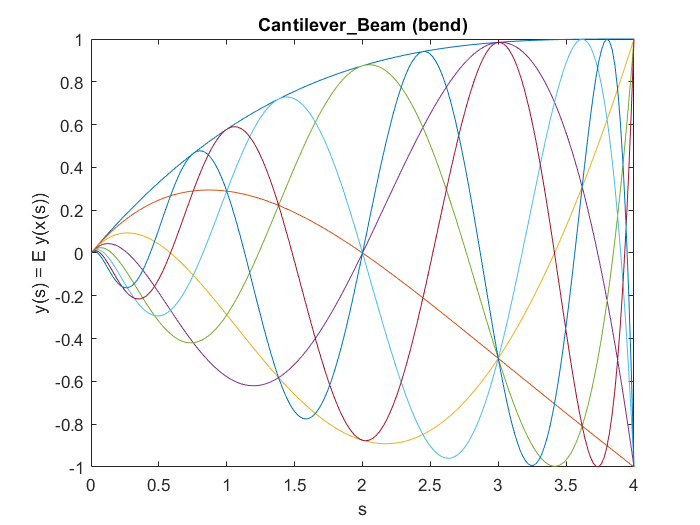

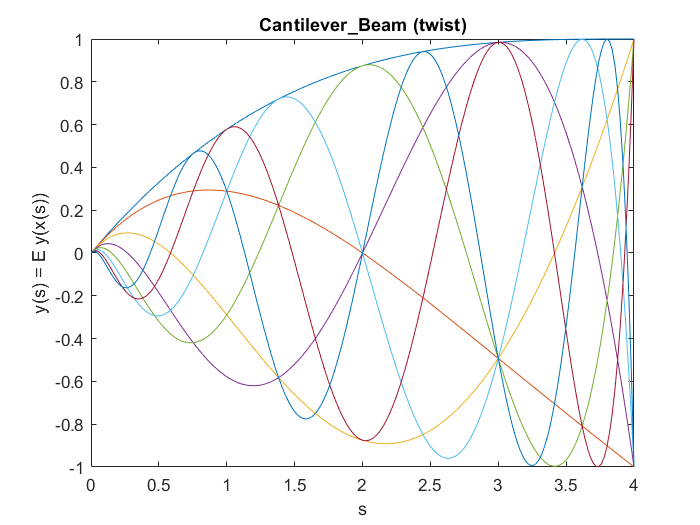

Mcb_obj.plotShapes();

## Finalise the object

We are now at the stage where we have a master object Mcb_obj containing all of the problem information including a child object Pcb_obj referring specifically to the flexible beam. To finalise this object we input the command

Mcb_obj.set_dependent_properties();

This manually populates the remaining dependent properties of the master and part objects.

[Note that true dependent properties are largely avoided in the formulation to avoid the unnecessary recalculation of parameters when accessed during each integration step. The set_dependent_properties method may be removed in subsequent versions of the code].

## Simulate the cantilever beam system

We will now simulate this cantilever beam system. It is important to note here that the NBS_master object and child objects contained within it are all handle classes. Thus to avoid issues when running multiple simulation cases on this system we will create copies of 'Mcb_obj' using its own copy method.

Mcb_obj_static = Mcb_obj.copy();

(Note: The created copy Mcb_obj_static is entirely unlinked from the original Mcb_obj and thus changes to one will not affect the other. However, Mcb_obj_static has retained exactly the same handle architecture and properties as the original Mcb_obj)

Simulation of the system is executed by the 'runSim' function.

Mcb_obj_static = runSim(0,1,'analysisType','static','fromObject',Mcb_obj_static);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         25         60157.8                      3.85e+05               1
     1         50         226.305       0.437923       3.22e+04               1
     2         75      0.00177316      0.0227796           93.2            1.09
     3        100     1.12035e-13    6.40241e-05       0.000748            1.09
     4        125     1.17182e-26    5.08898e-10       1.31e-09            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

Use the draw method to display deformed solution.

Mcb_obj_static.draw();
title('Cantilever Beam Deflection - Self Weight');

Various quantities of interest can be extracted from the simulated object. We will not go into this in detail for this example. For now, the tip displacement is extracted from the static solution using the command:

TipPosition = Mcb_obj_static.get_qoiValue('Cantilever_Beam','Gamma_G','Tidx','nt','Sidx','ns'),

TipPosition =          0
    3.7826
   -1.2151


A dynamic simulation may also be performed on the cantilever system. The code below executes this over a simulated period of 20 seconds.

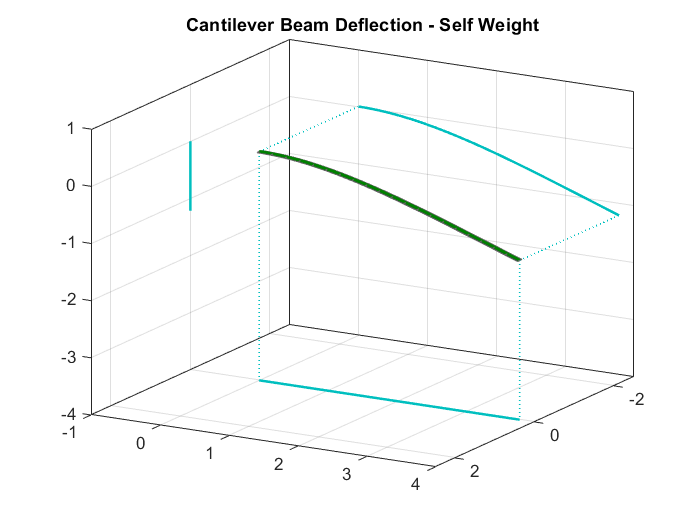

runTime: 20.8522


Mcb_obj_dynamic = Mcb_obj.copy;
t_start = 0;
t_end = 20;
Mcb_obj_dynamic = runSim(t_start,t_end,'fromObject',Mcb_obj_dynamic);

Again, we access the tip displacement of the beam, this time over the course of the dynamic simulation.

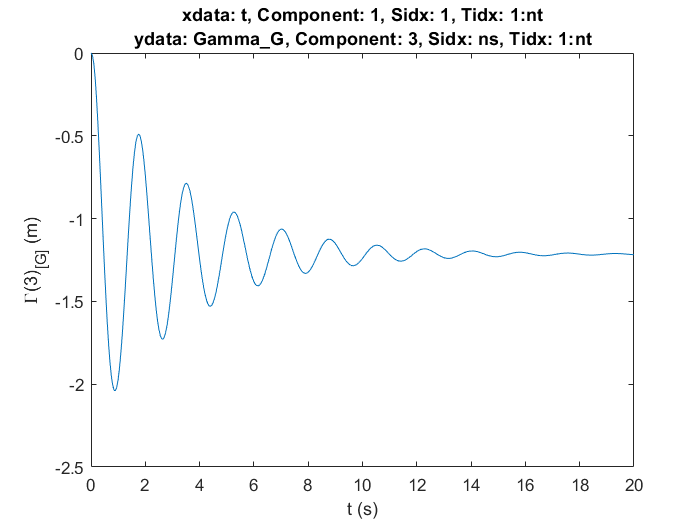

Mcb_obj_dynamic.generate_2dplot('Cantilever_Beam',{'t',1,'1','1:nt'},{'Gamma_G',3,'ns','1:nt'});

**Adding a Tip Load**

For the final part of this example, two tip loads will be added in turn to the cantilever beam.

The first will be a follower force, this always has the same orientation relative to the beam at its application point (thus the force vector in the intrinsic coordinate system is constant). The force will initially act in the vertical downwards direction with a magnitude of -500 N.

First, lets retrieve the part object from the NBS_Master object.

Pcb_obj_static = Mcb_obj_static.get_partObj('Cantilever_Beam');

Now add the follower force.

Pcb_obj_static.tip_force_local = [0;0;-500];
Pcb_obj_static.tip_force_global = [0;0;0];

Calculate the static deflection.

Mcb_obj_static = runSim(0,1,'analysisType','static','fromObject',Mcb_obj_static);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         25     3.58834e+06                      5.35e+06               1
     1         50     1.50406e+06              1       2.51e+06               1
     2         75         83706.9         1.4455       8.24e+05             2.5
     3        100         17.2913       0.286548       2.08e+04            3.61
     4        125     7.22388e-07      0.0042798           4.84            3.61
     5        150     6.48738e-21    8.84146e-07       2.37e-06            3.61
     6        175     2.01176e-24    2.44931e-13       2.85e-08            3.61

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toleran

Plot the deformed shape using the draw method.

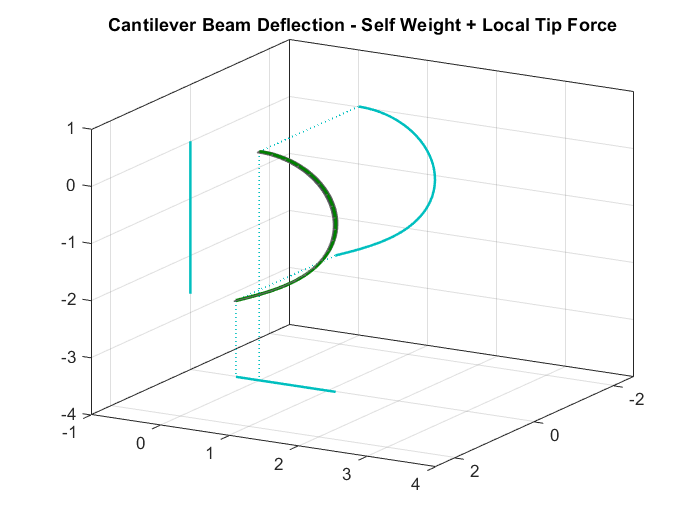

Mcb_obj_static.draw();
title('Cantilever Beam Deflection - Self Weight + Local Tip Force');

Next, this tip load is changed to a global force (constant in the global coordinate system).

Pcb_obj_static.tip_force_local = [0;0;0];
Pcb_obj_static.tip_force_global = [400;0;-100];

Again, simulate the static system.

Mcb_obj_static = runSim(0,1,'analysisType','static','fromObject',Mcb_obj_static);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         25      2.0958e+06                      4.24e+08               1
     1         50          449889              1       6.24e+07               1
     2         51          449889              1       6.24e+07               1
     3         52          449889           0.25       6.24e+07            0.25
     4         77          390879         0.0625        1.2e+08          0.0625
     5        102          328223        0.15625       3.43e+08           0.156
     6        103          328223        0.15625       3.43e+08           0.156
     7        128          265714      0.0390625       9.95e+07          0.0391
     8        153          214731      0.0976563       1.33e+08          0.0977
     9        154          214731       0.244141       1.33e+08           0.244
    10        179          181489      0.06

Plot the static deformation of the beam.

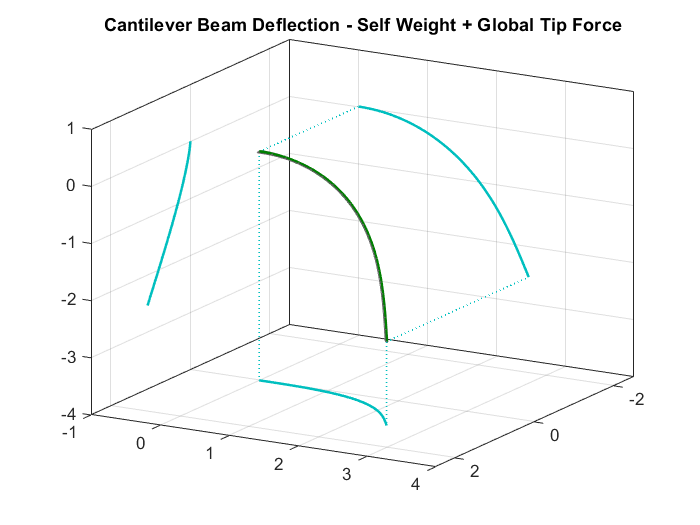

Mcb_obj_static.draw();
title('Cantilever Beam Deflection - Self Weight + Global Tip Force');

# Clamped Patil Hodges Wing

The following test case is based upon the Patil/Hodges wing treated in [ref]; modified to give a spanwise variation in stiffness and chord.

Rather than input all of the parameter values in from the command line as before, this example illustrates the use of input files to generate the initial object. Specifically the files that contian the wing definition are

"+parameter_sets \ testCase_ClampedPatilHodgesWing.m" - to define the NBS_Master object

and

"+parameter_sets \ +FlexPart_Library \ flexPart_Patil_Hodges_16m_halfWing.m" - to define the flexible part representing the wing

These files are now briefly examined.

## NBS_Master Object

'.\+parameter_sets\testCase_ExampleClampedWing.m';

Compared to the previous cantilever beam example, the main difference in the above code is the definition of the flight condition relavent to this aeroelastic test case. Specifically, the free stream velocity 'V', air density 'rho' and free-stream unit flow vector 'uvec_freeStream_G' are assigned values.

Additionally, an unsteady strip theory representation of the aerodynamics is requested.

## Flexible Part Object

'.\+parameter_sets\+FlexPart_Library\flexPart_ExampleWing.m';

The flexible part object specifying the wing parameters is given above. Once again, in addition to the parameters of the previous example, extra properties pertaining to the aerodynamics are given here. Specifically:

- the provision of 's_aero' defines the aero panel edge locations, i.e. nAnodes = 17 -> 17 s_aero points -> 16 aerodynamic panels

- 'isAero' dictates that this flexible part can generate aerodynamic loads

- 'c' is the aerodynamic chord of the wing

- 'beam_cntr' is the fractional location - from 0-leading edge to 1 trailing edge - along the aerodynamic panels at which the beam axis lies

- 'AICs' these are the span varying influence coefficients that shape the aerodynamic distribution (elliptical in this example). These AIC coefficients directly multiply the loads calculated by the strip theory aerodynamics

- 'CrossSectionProfiles', used in plotting the wing. Here the cross section of the wing is given a NACA0012 profile.

**Simulate the system**

To call the formulation using these files we use the 'testCase' keyword followed by an identifier string. The referenced file must have the address and file name of the form '.\+parameter_sets\testCase_[identifier string].m'.

i.e. for this example:

T0 = 0; T1 = 20;
Mcph_obj_dynamic = runSim(T0,T1,'analysisType','dynamic','testCase','ExampleClampedWing');

runTime: 13.6852


Generate a 2d plot of the tip displacement over time.

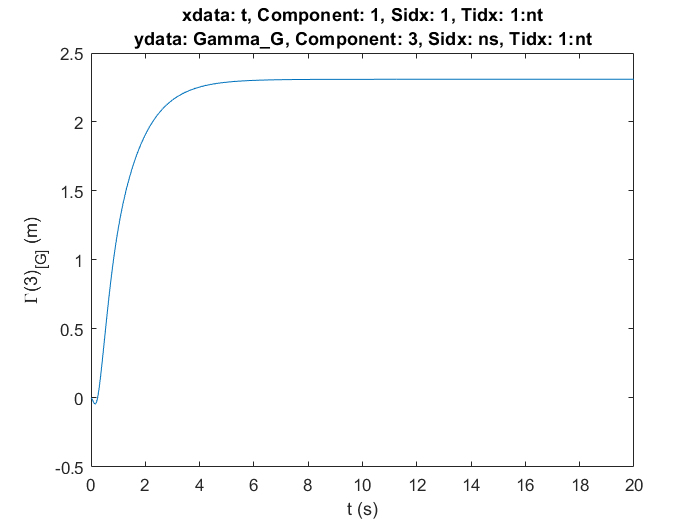

Mcph_obj_dynamic.generate_2dplot('halfWing',{'t',1,'1','1:nt'},{'Gamma_G',3,'ns','1:nt'});

Plot the final shape of the wing at t = 20 seconds.

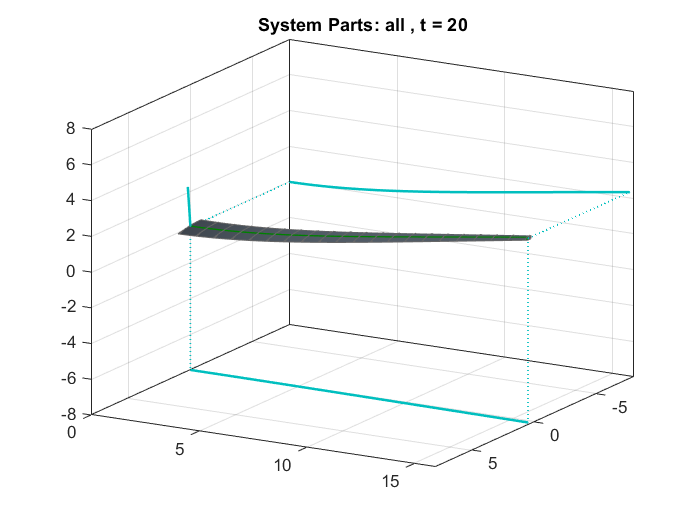

Mcph_obj_dynamic.draw('t',20);

Plot the aerodynamic lift distribution over the wing.

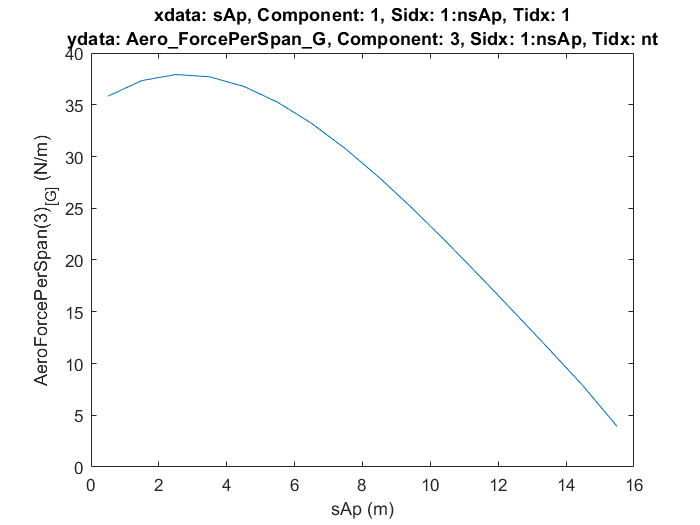

Mcph_obj_dynamic.generate_2dplot('halfWing',{'sAp',1,'1:nsAp','1'},{'Aero_ForcePerSpan_G',3,'1:nsAp','nt'});

We can choose to trim the wing using the method staticTrim. As an example, we consider here the the root angle of attack required to produce a net lift over the entire wing of 120 N. The method call takes the form detailed below with the user specifying the trim variables, trim quantities and the objects containing them.

property_to_vary = 'alpha_root';
object_containing_property = 'halfWing';
quantity_to_trim = 'Net_Lift';
object_containing_quantity_to_trim = 'aircraft';
trim_quantity_value = 120;

partName_partProperty = {object_containing_property , property_to_vary};
partName_QOIName_QOIValue = {object_containing_quantity_to_trim , quantity_to_trim , trim_quantity_value};

Mcph_obj_dynamic.staticTrim(partName_partProperty,partName_QOIName_QOIValue);

runTime: 4.1909
    4.0000  148.6722



runTime: 4.8623
    4.0000  148.6722



runTime: 4.8645
    3.2248  119.9618



runTime: 4.9593
    3.2248  119.9618



runTime: 4.9151
    3.2258  120.0000



runTime: 4.8572
    3.2258  120.0000



runTime: 4.9085
    3.2258  120.0000



runTime: 4.9339
    3.2258  120.0000


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


# **Full Aircraft Example**

The following example will detail the setting up of a full aircraft model. The testcase file that will be loaded for this example is

'.\+parameter_sets\testCase_ExampleFullAC.m';

The contents of this test case file are shown below:

In the code above, one can see that this aircraft is constructed by first creating the NBS_Master object. Then adding a starboard wing, port wing, fuselage and horizontal tail plane (HTP) to the object. The individual files describing each part can be found in the folder locations

'.\+parameter_sets\+FlexPart_Library'; %for the flexible wings
'.\+parameter_sets\+RigidPart_Library'; %for the rigid fuselage and HTP parts

We simulate this system in the same way as the previous examples, using the runSim function.

T0 = 0; T1 = 2;
Mcph_obj_dynamic = runSim(T0,T1,'analysisType','dynamic','testCase','ExampleFullAC');

As well as the previous plot generating functions, a video can also be generated of the dynamic response of the system. This is achieved with the generate_video method; for example.

Mcph_obj_dynamic.generate_video('plotCoM',false,'playSpeed',1,'framerate',5,'az',130);
implay('video.avi');

## A note on output generation

Note that the nonlinear beam shapes coded formulation contains a graphical user interface (GUI) to assist with the organisation of output quantities and the generation of plots. The functionality of this will be covered in detail in a separate guide. To use this feature the user must install the GUI layout toolbox in matlab, available from [here](https://uk.mathworks.com/matlabcentral/fileexchange/47982-gui-layout-toolbox).

Once the toolbox is installed, the GUI is accessible via the command:

Mcph_obj_dynamic.populate_QOIs();